Laboratory 4 - Problem No.1

clc;
close all;
clear all;

F = 1;
Sim_Time = 25;

M1 = 1;
M2 = 1;
M3 = 1;

k1 = 1;
k2 = 1;
k3 = 1;

B1 = 1;
B2 = 1;
B3 = 1;
B4 = 1;

A = [0 1 0 0 0 0;
     -((k1+k2)/M1) -((B4+B3)/M1) k2/M1 0 0 B3/M1;
     0 0 0 1 0 0;
     k2/M2 0 -(k2/M2) -((B2+B4)/M2) 0 B4/M2;
     0 0 0 0 0 1;
     0 B1/M3 0 B2/M3 0 -((B3+B4)/M3)];

B = [0;
     0;
     0
     1/M2;
     0;
     0];

C = [1 0 0 0 0 0;
     0 0 1 0 0 0;
     0 0 0 0 1 0];


D = [0;
     0;
     0];

ss_Laboratory_4_Problem_1 = ss(A,B,C,D)


ss_Laboratory_4_Problem_1 =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   1   0   0   0   0
   x2  -2  -2   1   0   0   1
   x3   0   0   0   1   0   0
   x4   1   0  -1  -2   0   1
   x5   0   0   0   0   0   1
   x6   0   1   0   1   0  -2
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
   x5   0
   x6   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
   y3   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


tf(ss_Laboratory_4_Problem_1)


ans =
 
  From input to output...
                       2 s + 2
   1:  ---------------------------------------
       s^5 + 6 s^4 + 13 s^3 + 16 s^2 + 8 s + 2
 
                s^3 + 4 s^2 + 5 s + 4
   2:  ---------------------------------------
       s^5 + 6 s^4 + 13 s^3 + 16 s^2 + 8 s + 2
 
              s^3 + 2 s^2 + 3 s - 3.281e-16
   3:  -------------------------------------------
       s^6 + 6 s^5 + 13 s^4 + 16 s^3 + 8 s^2 + 2 s
 
Continuous-time transfer function.


hold on
sim("Laboratory_4_Problem_1.slx")

ans =   Simulink.SimulationOutput:

                      C: [1x1 timeseries] 
                      F: [1x1 timeseries] 
                   tout: [58x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


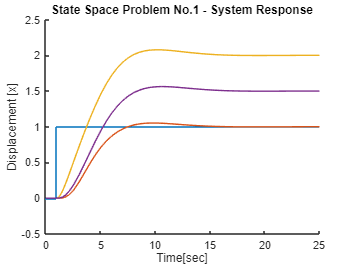

hold on
plot(ans.F);
plot(ans.C);
ylabel("Displacement [x]");
xlabel("Time[sec]");
title('State Space Problem No.1 - System Response');